# 5. Suponha que o(s) motor(es) de um aviao pode(m) falhar com probabilidade p e que as falhas sao independentes entre motores. Suponha ainda que o aviao se despenha se mais de metade dos motores falharem. Nestas condicoes, prefere voar num aviao com 2 ou 4 motores? Utilize a distribuicao que considerar mais adequada

## Sugestao: Tem pelo menos 2 alternativas: (1) obter expressoes para a probabilidade de cada tipo de aviao se despenhar em funcao de p e usar o quociente entre ambas para responder a questao, (2) efectuar os calculos para um conjunto de valores concretos 2 de p (ex: p= logspace(-3,log10(1/2),100)) e usar um grafico mostrando simultaneamente as probabilidades de cada tipo de aviao se despenhar

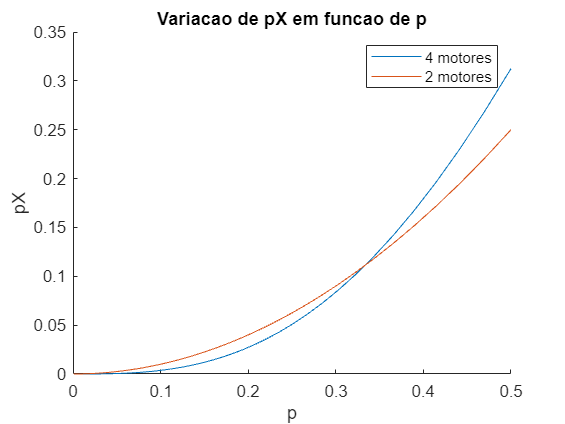

% X = numero de motores que falham
%Podemos considerar que X e uma variavel binomial onde temos sucesso caso o motor falhe, e insucesso caso nao falhe
%Como X e uma variavel Binomial: %pX(k) = nCk * p^k * (1-p)^(n-k) = n! / (k! * (n-k)!) * p^k * (1-p)^(n-k)

%Vamos calcular a probabilidade de cair um aviao com 2 motores, repetir a experiencia para o de 4 motores, e comparar os resultados

%Aviao de 2 motores -> despenha se quando ambos os motores falharem (>50% dos motores falharem):
n = 2;
k = 2;
p = logspace(-3, log10(1/2),100);
nCk = factorial(n)/(factorial(k) * factorial(n-k));

p2Motores = nCk .* p.^k .* (1-p).^(n-k);

%Aviao de 4 motores -> despenha se 3 ou 4 motores falharem

p4Motores = 0;
n = 4;

k = 3;
nCk = factorial(n)/(factorial(k) * factorial(n-k));
p4Motores = p4Motores + nCk .* p.^k .* (1-p).^(n-k);

k = 4;
nCk = factorial(n)/(factorial(k) * factorial(n-k));
p4Motores = p4Motores+ nCk .* p.^k .* (1-p).^(n-k);

figure(1);
hold on;

x = logspace(-3, log10(1/2),100);

plot(x,p4Motores);

plot(x,p2Motores);

legend("4 motores","2 motores");

xlabel('p');
ylabel('pX');
title("Variacao de pX em funcao de p");

hold off;


%% Ate os dois graficos se intercetarem (analisando o grafico, a mais ou menos p =  0.33) e mais seguro viajar no aviao com 4 motores. A partir dai porém, e prerefirvel viajar no aviao com 2 motores